## Очищення середовища

clear, close all

## 1.Завантаження тестового зображення

image = imread('cameraman.tif');

## 2.Відображення вихідного зображення для перевірки

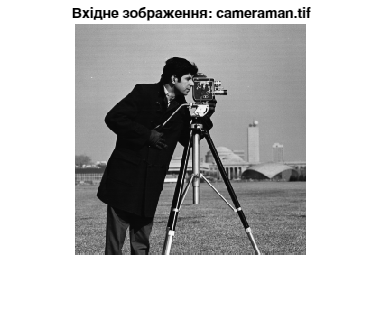

figure, imshow(image), title('Вхідне зображення: cameraman.tif');

## 3.Заманане зображення

LEN = 21;
THETA = 0;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(image, PSF, 'conv', 'circular');

## 4.Відображення замазаного зображення

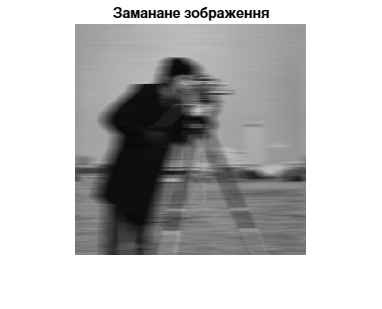

figure, imshow(blurred), title('Заманане зображення');

## 5.Відновлення зображення

recovered = deconvwnr(blurred, PSF, 0);

## 6.Відображення відновленого зображення

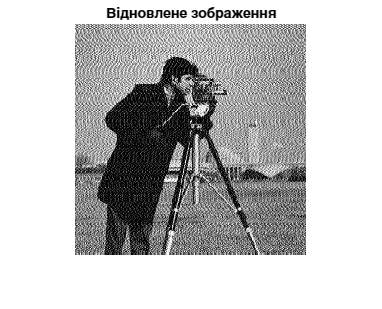

imshow(recovered),title('Відновлене зображення');

## 7. Виконати зашумлення початкового зображення та повторити пункти 2-6:

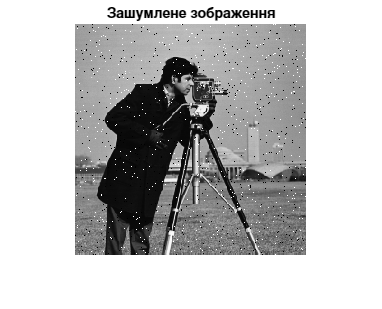

noisy_image = imnoise(image, 'salt & pepper', 0.02);
figure, imshow(noisy_image), title('Зашумлене зображення');

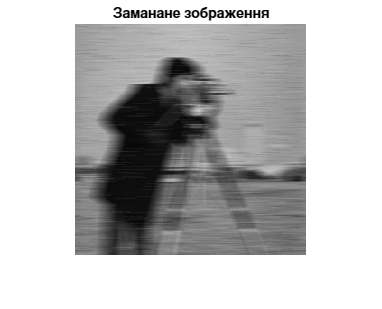


noisy_blurred = imfilter(noisy_image, PSF, 'conv', 'circular');
figure, imshow(noisy_blurred), title('Заманане зображення');

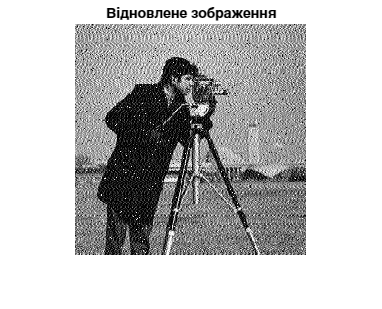


noisy_recovered = deconvwnr(noisy_blurred, PSF, 0);
imshow(noisy_recovered),title('Відновлене зображення');

# 8.Контрольні питання

### **1. Поясніть процес формування зображення:**

Процес формування зображення полягає в перетворенні реальної сцени на цифрове зображення. Світло, що відбивається від об'єкта, проходить через оптичну систему (наприклад, об'єктив), потрапляє на сенсор (матрицю), де кожен піксель фіксує рівень інтенсивності світла. Це аналогове значення потім оцифровується і перетворюється на цифрове зображення.

### **2. Опишіть модель формування зображень та лінійних перекручень:**

Математично процес формування зображення можна описати рівнянням:

**g(x, y) = h(x, y) * f(x, y) + n(x, y)**

де:

- *f(x, y)* — оригінальне зображення,

- *h(x, y)* — функція розмивання (PSF),

- *n(x, y)* — шум,

- *g(x, y)* — отримане перекручене зображення,

- *** — операція згортки.

Лінійні перекручення включають розмиття (наприклад, рухове розмиття, дефокусування) або шум, що описуються лінійними операціями над зображенням.

### **3. Поясніть процес відновлення перекрученого зображення:**

Відновлення зображення — це процес відтворення оригінального зображення f(x,y)f(x, y) *f(x, y)* за відомим *g(x, y)*. Застосовують методи:

- **Інверсна фільтрація** (Inverse Filtering) — коли відома *h(x, y)*,

- **Фільтрація Вінера** — враховує і шум, і розмиття,

Ці методи працюють у частотній або просторовій області.